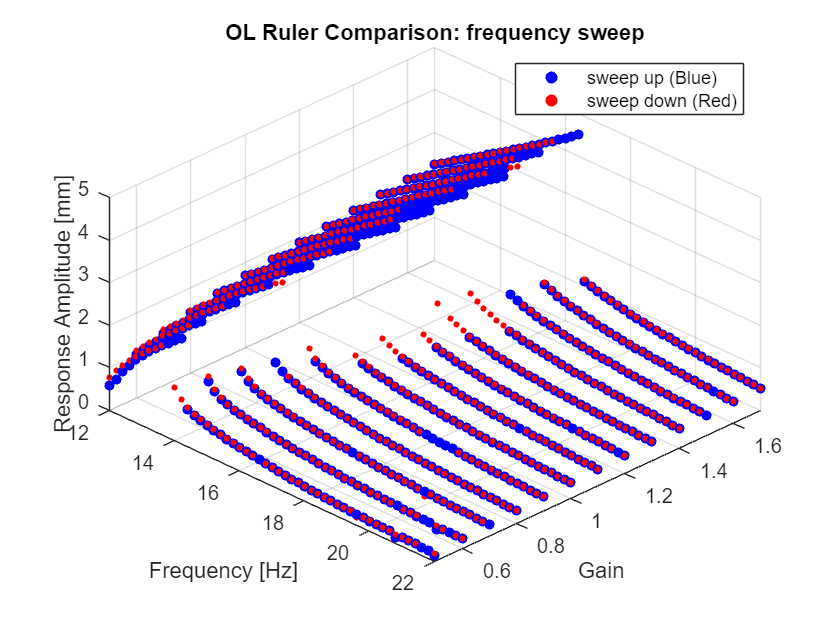

close all;
clear all;
% === Parameters ===
folder17 = "saves/OL_blade_up/";
folder18 = "saves/OL_blade_down/";
freq_range_17 = 12:0.2:22;
freq_range_18 = 22:-0.2:12;

% === Detect Files ===
files17 = dir(fullfile(folder17, "ruler_amp_*.mat"));
files18 = dir(fullfile(folder18, "ruler_amp_*.mat"));

% === Extract gain strings (e.g., '01_50') ===
gains17 = extractBetween({files17.name}, "ruler_amp_", ".mat");
gains18 = extractBetween({files18.name}, "ruler_amp_", ".mat");

% === Combine and deduplicate ===
all_gain_names = unique([gains17, gains18]);
getGain = @(str) str2double(strrep(str, "_", "."));  % '23_56' → 23.56

% === Plot ===
figure;
hold on;

for i = 1:length(all_gain_names)
    name = all_gain_names{i};           % e.g. '01_50'
    gain_val = getGain(name);           % e.g. 1.5

    % --- 17 July ---
    file_path_17 = fullfile(folder17, "ruler_amp_" + name + ".mat");
    if isfile(file_path_17)
        try
            data17 = load(file_path_17).data_out;
            N17 = size(data17, 1);
            freq17 = linspace(freq_range_17(1), freq_range_17(end), N17);
            amp17 = data17(:, 2);
            force17 = data17(:, 3);
            % scatter3(freq17, force17, amp17, 25, 'b', 'filled');
            scatter3(freq17, gain_val * ones(size(freq17)), amp17, 25, 'b', 'filled');
        catch
            warning("Problem loading: %s", file_path_17);
        end
    end

    % --- 18 July ---
    file_path_18 = fullfile(folder18, "ruler_amp_" + name + ".mat");
    if isfile(file_path_18)
        try
            data18 = load(file_path_18).data_out;
            N18 = size(data18, 1);
            freq18 = linspace(freq_range_18(1), freq_range_18(end), N18);
            amp18 = data18(:, 2);
            force18 = data18(:, 3);
            scatter3(freq18, gain_val * ones(size(freq18)), amp18, 10, 'r', 'filled');
            % scatter3(freq18, force18, amp18, 10, 'r', 'filled');

        catch
            warning("Problem loading: %s", file_path_18);
        end
    end
end

% === Final Labels and View ===
xlabel("Frequency [Hz]");
ylabel("Gain");
zlabel("Response Amplitude [mm]");
title("OL Ruler Comparison: frequency sweep");
legend({'sweep up (Blue)', 'sweep down (Red)'});
grid on;
view([45, 45]);  % Side-on view

view([0, 0]);
y_val = 1.3

y_val = 1.3000

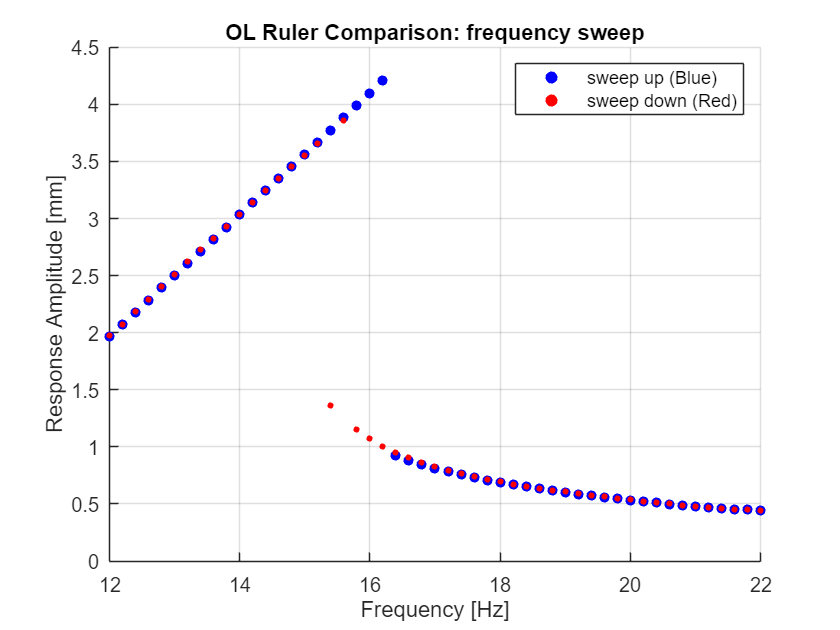

ylim([y_val-0.01, y_val+0.01])